# Práctica 2 - Cortocircuitos II - Apartado C

#### Falta monofásica (F10) en el punto F1 en función de x, usando la matriz de barras

## Sistemas Eléctricos y de Potencia

### Subgrupo 10

NOTA. Aquí se usa el índice 3 para lasecuencia homopolar debido a la negativa de Matlab a trabajar con vectores empezando en 0.

format shortG
sympref('FloatingPointOutput', true);
if ~exist('ZF1N', 'var')
    evalc('Practica2B');
end

## Impedancia en secuencia directa e inversa

La impedancia en secuencia directa es la misma que en secuencia directa (Z1 = Z2)

Z1F1_eq(x) = ZF1N

$$Z1F1\_eq(x) = -0.0871\,x^{2}\,\mathrm{i}+0.1183\,x\,\mathrm{i}+0.1844\,\mathrm{i}$$

Z2F1_eq(x) = Z1F1_eq

$$Z2F1\_eq(x) = -0.0871\,x^{2}\,\mathrm{i}+0.1183\,x\,\mathrm{i}+0.1844\,\mathrm{i}$$

## Circuito monofásico equivalente en secuencia homopolar

% Valor de x (10% - 90%)
x_val =70;

% Valores de todas las admitancias iniciales
Y12 = 1/ZL12pu(3);
Y14 = 1/ZL14pu(3);
Y23 = 1/ZL23pu(3);
Y24 = 1/ZL24pu(3);
Y35 = 1/ZL35pu(3);
Y4F1 = 1/ZL4Xpu(3);
Y5N = 1/ZT5pu(3);
Y5F1 = 1/ZL5Xpu(3);

## Matriz de admitancias y de impedancias en secuencia homopolar

El índice 6 corresponde al punto de falta F1 

% Matriz de admitancias
Ybarras0 = [Y12+Y14, -Y12       , 0       , -Y14        , 0           , 0        ;
           -Y12    , Y12+Y23+Y24, -Y23    , -Y24        , 0           , 0        ;
           0       , -Y23       , Y23+Y35 , 0           , -Y35        , 0        ;
           -Y14    , -Y24       , 0       , Y14+Y24+Y4F1, 0           , -Y4F1    ;
           0       , 0          , -Y35    , 0           , Y5N+Y35+Y5F1, -Y5F1    ;
           0       , 0          , 0       , -Y4F1       , -Y5F1       , Y4F1+Y5F1];
Ybarras0 = simplify(Ybarras0) % se simplifica para que se vea mejor

$$Ybarras0 = \begin{array}{l} \left(\begin{array}{cccccc} -12.8118\,\mathrm{i} & 10.2494\,\mathrm{i} & 0 & 2.5624\,\mathrm{i} & 0 & 0\\ 10.2494\,\mathrm{i} & -17.1891\,\mathrm{i} & 5.1247\,\mathrm{i} & 1.8150\,\mathrm{i} & 0 & 0\\ 0 & 5.1247\,\mathrm{i} & -6.9397\,\mathrm{i} & 0 & 1.8150\,\mathrm{i} & 0\\ 2.5624\,\mathrm{i} & 1.8150\,\mathrm{i} & 0 & -\frac{1.8150\,\mathrm{i}}{x}-4.3774\,\mathrm{i} & 0 & \frac{1.8150\,\mathrm{i}}{x}\\ 0 & 0 & 1.8150\,\mathrm{i} & 0 & -\frac{0.0017\,\left(3589\,x-4678\right)\,\mathrm{i}}{x-1} & \sigma_{1}\\ 0 & 0 & 0 & \frac{1.8150\,\mathrm{i}}{x} & \sigma_{1} & \frac{1.8150\,\mathrm{i}}{x\,\left(x-1\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{1.8150\,\mathrm{i}}{x-1} \end{array}$$


% Matriz de impedancias
Zbarras0 = inv(Ybarras0);
Zbarras0 = simplify(Zbarras0) % se simplifica para que se vea mejor

$$Zbarras0 = \begin{array}{l} \left(\begin{array}{cccccc} 0.6653\,\mathrm{i} & 0.6035\,\mathrm{i} & 0.5084\,\mathrm{i} & 0.5225\,\mathrm{i} & 0.2400\,\mathrm{i} & \sigma_{1}\\ 0.6035\,\mathrm{i} & 0.6283\,\mathrm{i} & 0.5267\,\mathrm{i} & 0.5042\,\mathrm{i} & 0.2400\,\mathrm{i} & \sigma_{2}\\ 0.5084\,\mathrm{i} & 0.5267\,\mathrm{i} & 0.5958\,\mathrm{i} & 0.4351\,\mathrm{i} & 0.2400\,\mathrm{i} & \sigma_{3}\\ 0.5225\,\mathrm{i} & 0.5042\,\mathrm{i} & 0.4351\,\mathrm{i} & 0.5958\,\mathrm{i} & 0.2400\,\mathrm{i} & \sigma_{4}\\ 0.2400\,\mathrm{i} & 0.2400\,\mathrm{i} & 0.2400\,\mathrm{i} & 0.2400\,\mathrm{i} & 0.2400\,\mathrm{i} & 0.2400\,\mathrm{i}\\ \sigma_{1} & \sigma_{2} & \sigma_{3} & \sigma_{4} & 0.2400\,\mathrm{i} & -0.1951\,x^{2}\,\mathrm{i}-0.1607\,x\,\mathrm{i}+0.5958\,\mathrm{i} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-0.2825\,x\,\mathrm{i}+0.5225\,\mathrm{i}\\ \sigma_{2}=-0.2642\,x\,\mathrm{i}+0.5042\,\mathrm{i}\\ \sigma_{3}=-0.1951\,x\,\mathrm{i}+0.4351\,\mathrm{i}\\ \sigma_{4}=-0.3558\,x\,\mathrm{i}+0.5958\,\mathrm{i} \end{array}$$

## Impedancia en secuencia homopolar

Correspondiente con el valor (6,6) de la matriz de impedancias

% Valor por unidad en función de x
Z0F1_eq(x) = Zbarras0(6,6)

$$Z0F1\_eq(x) = -0.1951\,x^{2}\,\mathrm{i}-0.1607\,x\,\mathrm{i}+0.5958\,\mathrm{i}$$


% Valor por unidad sustituyendo x
Z0F1_eq(x_val/100)

$$ans = 0.3877\,\mathrm{i}$$

## Valor de la corriente de falta monofásica (F10) en el punto F1

Los valores de las corrientes de cada secuencia son iguales, J1 = J2 = J0 = 1/3 JF = Upf/(Z0 + Z1 + Z2)

% Valor por unidad en función de x
JF1_F10_pu(x) = 3*Upf_F1/(Z1F1_eq + Z2F1_eq + Z0F1_eq)

$$JF1\_F10\_pu(x) = \frac{3.1500}{-0.3692\,x^{2}\,\mathrm{i}+0.0760\,x\,\mathrm{i}+0.9646\,\mathrm{i}}$$


% Valor por unidad sustituyendo x
JF1_F10_pu(x_val/100)

$$ans = -3.7641\,\mathrm{i}$$


% Valor real (en amperios) en función de x
JF1_F10(x) = JF1_F10_pu*Ibase_F1

$$JF1\_F10(x) = \frac{1.3778e+03}{-0.3692\,x^{2}\,\mathrm{i}+0.0760\,x\,\mathrm{i}+0.9646\,\mathrm{i}}$$


% Valor real (en amperios) sustituyendo x
JF1_F10(x_val/100)

$$ans = -1.6464e+03\,\mathrm{i}$$

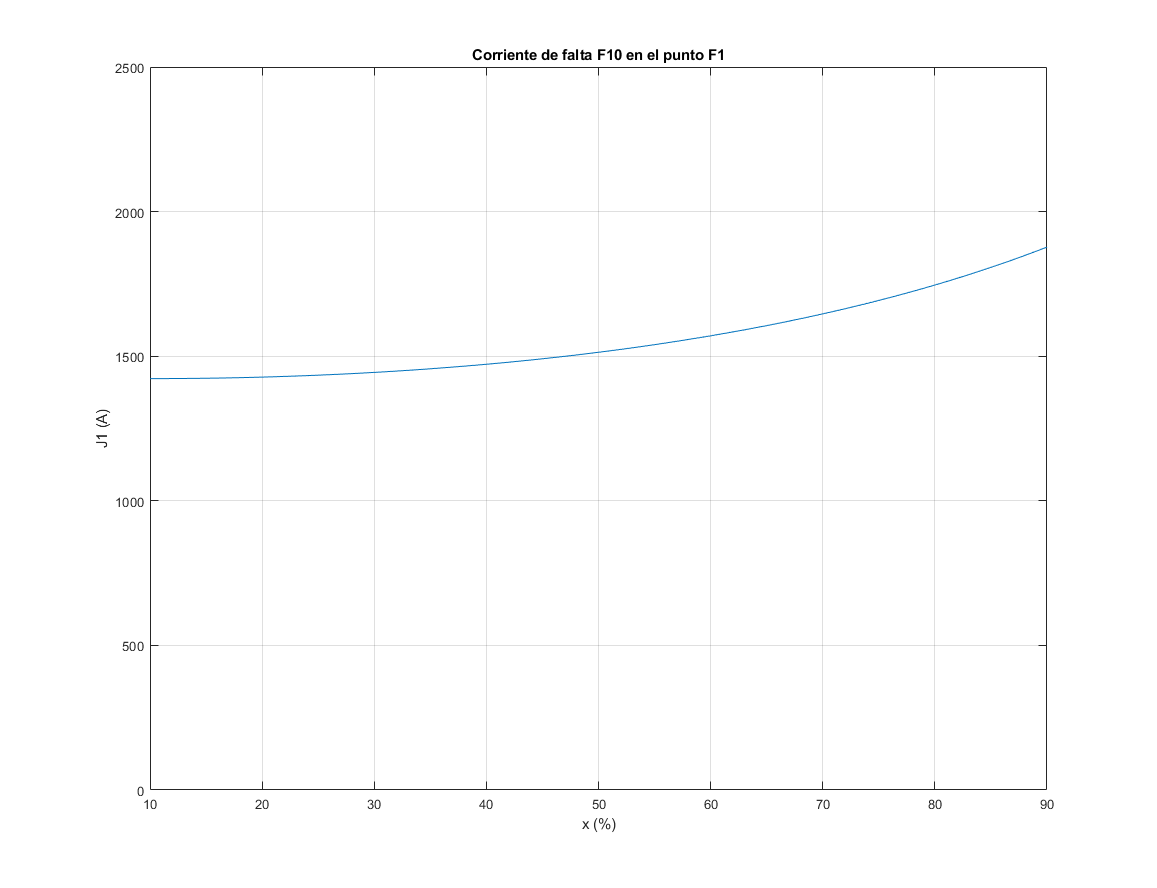


% Representación gráfica de la corriente de falta en función de x (en
% módulo)
xF1 = 10:90;
plot(xF1, abs(JF1_F10(xF1/100)));
title('Corriente de falta F10 en el punto F1');
xlabel('x (%)');
ylabel('J1 (A)');
grid on;
ylim([0, 2500]);

% Corrientes de secuencia en función de x
J0 = JF1_F10/3; 
J012(x) = ([J0; J0; J0])% J1 y J2 son iguales a J0

$$J012(x) = \left(\begin{array}{c} \frac{459.2559}{-0.3692\,x^{2}\,\mathrm{i}+0.0760\,x\,\mathrm{i}+0.9646\,\mathrm{i}}\\ \frac{459.2559}{-0.3692\,x^{2}\,\mathrm{i}+0.0760\,x\,\mathrm{i}+0.9646\,\mathrm{i}}\\ \frac{459.2559}{-0.3692\,x^{2}\,\mathrm{i}+0.0760\,x\,\mathrm{i}+0.9646\,\mathrm{i}} \end{array}\right)$$


% Corrientes de secuencia sustituyendo x
J012(x_val/100)

$$ans = \left(\begin{array}{c} -548.7913\,\mathrm{i}\\ -548.7913\,\mathrm{i}\\ -548.7913\,\mathrm{i} \end{array}\right)$$


% Corrientes de fase en función de x
Jabc(x) = T*J012

$$Jabc(x) = \left(\begin{array}{c} \frac{1.3778e+03}{-0.3692\,x^{2}\,\mathrm{i}+0.0760\,x\,\mathrm{i}+0.9646\,\mathrm{i}}\\ 0\\ 0 \end{array}\right)$$


% Corrientes de fase sustituyendo x
Jabc(x_val/100)

$$ans = \left(\begin{array}{c} -1.6464e+03\,\mathrm{i}\\ 0\\ 0 \end{array}\right)$$